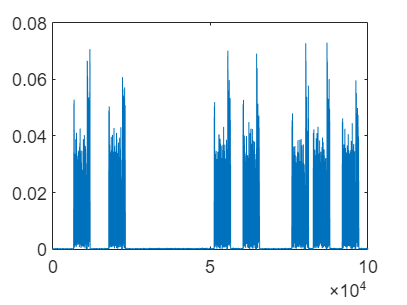

clear all
clc
clf

load('cfgNonHT.mat')
PSDULength = 132;

rx_packet = read_complex_binary('./rawSample/exp2/l_2_1.dat');
% rx_packet = rx_packet(4000:end);
rx_packet = rx_packet(1e6:2e6);

% plot(abs(rx_packet(4000:end)))
% rx_packet = rx_packet(1.05400e5:1.09e5);
rx_packet_abs_corr = abs(Correlate(rx_packet,1)); 
plot(abs(rx_packet_abs_corr(1:1e5)))

% pcapObj = pcapWriter('FileName','data_2.4G');
% wlanLinkType = 105;
% writeGlobalHeader(pcapObj,wlanLinkType);

BIT_NUM = 1056;
LLR_LEN = BIT_NUM + 16;

WIFI_SN  = zeros(1e4,1);
WIFI_CRC = zeros(1e4,1);

SSIC_SN = zeros(1e4,1);
SSIC_header_CRC = zeros(1e4,1);
SSIC_layload_CRC = zeros(1e4,1);

CONV_LLR_Collection = zeros(1e4,LLR_LEN);
SSIC_LLR_Collection = zeros(1e4,LLR_LEN);

window_size = 600;
power_threashold = 0.002;

trellis = poly2trellis(7,[133 171]);

appDecoder = comm.APPDecoder(...
    'TrellisStructure',trellis, ...
    'Algorithm','True APP','CodedBitLLROutputPort',false);

n = 63; k = 7; % Codeword length and message length
[gp,t] = bchgenpoly(n,k); % t is error-correction capability.
enc = comm.BCHEncoder(n,k,gp);
dec = comm.BCHDecoder(n,k,gp);

crcgenerator_crc3= comm.CRCGenerator('Polynomial','z^3 + z^2 + z + 1', ...
    'InitialConditions',1,'DirectMethod',true,'FinalXOR',1)

crcgenerator_crc3 =   comm.CRCGenerator with properties:

           Polynomial: 'z^3 + z^2 + z + 1'
    InitialConditions: 1
         DirectMethod: true
    ReflectInputBytes: false
     ReflectChecksums: false
             FinalXOR: 1
    ChecksumsPerFrame: 1


crcdetector_crc3  = comm.CRCDetector('Polynomial','z^3 + z^2 + z + 1', ...
    'InitialConditions',1,'DirectMethod',true,'FinalXOR',1)

crcdetector_crc3 =   comm.CRCDetector with properties:

           Polynomial: 'z^3 + z^2 + z + 1'
    InitialConditions: 1
         DirectMethod: true
    ReflectInputBytes: false
     ReflectChecksums: false
             FinalXOR: 1
    ChecksumsPerFrame: 1



crcgenerator_crc8 = comm.CRCGenerator('Polynomial','z^8 + z^2 + z + 1', ...
    'InitialConditions',1,'DirectMethod',true,'FinalXOR',1)

crcgenerator_crc8 =   comm.CRCGenerator with properties:

           Polynomial: 'z^8 + z^2 + z + 1'
    InitialConditions: 1
         DirectMethod: true
    ReflectInputBytes: false
     ReflectChecksums: false
             FinalXOR: 1
    ChecksumsPerFrame: 1


crcdetector_crc8 = comm.CRCDetector('Polynomial','z^8 + z^2 + z + 1', ...
    'InitialConditions',1,'DirectMethod',true,'FinalXOR',1)

crcdetector_crc8 =   comm.CRCDetector with properties:

           Polynomial: 'z^8 + z^2 + z + 1'
    InitialConditions: 1
         DirectMethod: true
    ReflectInputBytes: false
     ReflectChecksums: false
             FinalXOR: 1
    ChecksumsPerFrame: 1



crcgenerator_crc16 = comm.CRCGenerator('Polynomial','z^16 + z^14 + z + 1', ...
    'InitialConditions',1,'DirectMethod',true,'FinalXOR',1)

crcgenerator_crc16 =   comm.CRCGenerator with properties:

           Polynomial: 'z^16 + z^14 + z + 1'
    InitialConditions: 1
         DirectMethod: true
    ReflectInputBytes: false
     ReflectChecksums: false
             FinalXOR: 1
    ChecksumsPerFrame: 1


crcdetector_crc16  = comm.CRCDetector('Polynomial','z^16 + z^14 + z + 1', ...
    'InitialConditions',1,'DirectMethod',true,'FinalXOR',1)

crcdetector_crc16 =   comm.CRCDetector with properties:

           Polynomial: 'z^16 + z^14 + z + 1'
    InitialConditions: 1
         DirectMethod: true
    ReflectInputBytes: false
     ReflectChecksums: false
             FinalXOR: 1
    ChecksumsPerFrame: 1



N = 8;
scramInit = 93;

## Set the remaining variables for the simulation.

Get the baseband sampling rate

fs = wlanSampleRate(cfgNonHT);
% Indices for accessing each field within the time-domain packet

% Symbol-by-symbol streaming process
numDetectedPackets  = 0;
numValidPackets   = 0;
numinValidPackets   = 0;

dataTracker = 1;
rx_SN = 1;
pre_rx_SN = 1;
while dataTracker+window_size <= length(rx_packet)

    if rx_packet_abs_corr(dataTracker) >= power_threashold

        data = rx_packet(dataTracker:dataTracker+window_size);
        coarsePktOffset = wlanPacketDetect(data,cfgNonHT.ChannelBandwidth,0,0.7);

        if isempty(coarsePktOffset)
            dataTracker = dataTracker + window_size;
            continue 
        else
            dataTracker = dataTracker + coarsePktOffset;

            % Extract L-STF and perform coarse frequency offset correction
            data = rx_packet(dataTracker:dataTracker+window_size);
            lstf = data(1:160);

            coarseFreqOff = wlanCoarseCFOEstimate(lstf,cfgNonHT.ChannelBandwidth);
            data = helperFrequencyOffset(data,fs,-coarseFreqOff);

            % Extract the non-HT fields and determine fine packet offset
            nonhtfields = data(1:400);

            finePktOffset = wlanSymbolTimingEstimate(nonhtfields,...
                cfgNonHT.ChannelBandwidth);

            % Determine final packet offset
            dataTracker = dataTracker + finePktOffset;

            data = rx_packet(dataTracker:dataTracker+window_size);
            data = helperFrequencyOffset(data,fs,-coarseFreqOff);

            % Extract L-LTF and perform fine frequency offset correction
            lltf = data(161:320);
            fineFreqOff = wlanFineCFOEstimate(lltf,cfgNonHT.ChannelBandwidth);
            data = helperFrequencyOffset(data,fs,-fineFreqOff);

            lltf = data(161:320);

            NonhtltfDemod = wlanLLTFDemodulate(lltf,cfgNonHT.ChannelBandwidth);
            chanEst = wlanLLTFChannelEstimate(NonhtltfDemod,cfgNonHT.ChannelBandwidth);

            % Estimate the noise power in HT data field
            noiseVar = helperNoiseEstimate(NonhtltfDemod);
            syncedSym = data(321:400);

            [LSIGBits, failParityCheck] = wlanLSIGRecover(...
                syncedSym, chanEst, noiseVar, cfgNonHT.ChannelBandwidth, ...
                'EqualizationMethod', 'ZF');

            % L-SIG evaluation
            if ~failParityCheck
                % Recover packet parameters
                rate = bi2de(double(LSIGBits(1:3).'), 'left-msb');
                if rate <= 1
                    cfgNonHT.MCS = rate + 6;
                else
                    cfgNonHT.MCS = mod(rate, 6);
                end

                if bi2de(double(LSIGBits(6:17)')) == 0
                    dataTracker = dataTracker + window_size;
                    continue
                end
                cfgNonHT.PSDULength = bi2de(double(LSIGBits(6:17)'));
% 
%                % Obtain number of OFDM symbols in data field
                pNumDataSymbols = getNumDataSymbols(cfgNonHT);

                if cfgNonHT.PSDULength ~=  PSDULength
%                     dataTracker = dataTracker+ pNumDataSymbols*80  + 440;
                      dataTracker = dataTracker + window_size;
                      continue
                else
                    data = rx_packet(dataTracker:dataTracker+ pNumDataSymbols*80  + 400);
                    data = helperFrequencyOffset(data,fs,-coarseFreqOff);
                    data = helperFrequencyOffset(data,fs,-fineFreqOff);

                    numDetectedPackets = numDetectedPackets + 1;
                end
               
            else % L-SIG parity failed -- switch back to packet detection
                dataTracker = dataTracker + window_size;
                continue
            end

            ind = wlanFieldIndices(cfgNonHT);

            % Extract HT Data samples from the waveform
            rxNonHTData = data(ind.NonHTData(1):ind.NonHTData(2));

            [deintlvrOut,~,codingRate,PSDULength] = wlanNonHTCodedDataRecover(rxNonHTData, chanEst, ...
                noiseVar, cfgNonHT, 'EqualizationMethod', 'ZF');

            % Decoder
            if cfgNonHT.MCS == 6
                punct_vec  =  [1;1;1;0];
                punct_rate =  3/4;
            elseif cfgNonHT.MCS == 1 || cfgNonHT.MCS == 3 ||cfgNonHT.MCS == 5 ||cfgNonHT.MCS == 7
                punct_vec =  [1;1;1;0;0;1];
                punct_rate =  2/3;
            else
                punct_vec =  1;
                punct_rate = 1;
            end
            deintlvrOut = depuncturing(deintlvrOut, punct_vec,length(deintlvrOut)/punct_rate);

            % Channel decoding
            yLLR = appDecoder(zeros(length(deintlvrOut)*(1/2),1),-deintlvrOut);

            if length(yLLR)>= 16+8*PSDULength
                yLLR = yLLR(1:16+8*PSDULength);
            else
%                 dataTracker = dataTracker + pNumDataSymbols*80  + 440;
                dataTracker = dataTracker + window_size;
                continue
            end

            % Conventional Descraming
            [recBits,~,I] = wlanNonHTDescramer(double(yLLR > 0),PSDULength);
            
            % Decode and evaluate recovered bits
            [mpduCfg, payload, status] = wlanMPDUDecode(recBits, cfgNonHT);

            if strcmp(status, 'Success')
                numValidPackets = numValidPackets + 1;
                WIFI_SN(numDetectedPackets,:)  = mpduCfg.SequenceNumber;
                WIFI_CRC(numDetectedPackets,:) = 1;

            else
                numinValidPackets = numinValidPackets + 1;
                WIFI_SN(numDetectedPackets,:) = -1;
                WIFI_CRC(numDetectedPackets,:) = -1;
            end
            
            check_payload = dec2hex(bi2deOptimized(reshape(recBits(209:end), 8, [])'), 2);
            UDP_Payload = check_payload(end-69:end-4,:);
            rx_char_array_utf = char(hex2dec(UDP_Payload));
            char_array_native = unicode2native(rx_char_array_utf,'ISO-8859-1');

            %
            rx_bits_array = de2bi(char_array_native(:,:));
            rx_bits_array = reshape(rx_bits_array,[],8)';
            rx_bits_array = reshape(rx_bits_array,[],1);
            rx_bits = rx_bits_array ;
            
            %% Receiver
            rx_encData_header = rx_bits(1:189);
            [header_decData, nerrs] = step(dec, rx_encData_header); % Decode cnoisy.
            [header_rx_binary, header_CRC_err] = crcdetector_crc8(double(header_decData));
            header_rx_binary = wlanScramble(header_rx_binary,scramInit);
            
            rx_encData_payload = rx_bits(193:end);
            [payload_rx_binary, payload_CRC_err] = crcdetector_crc16(double(rx_encData_payload));

            if header_CRC_err == 0 
%                 pre_rx_SN = rx_SN;
                rx_SN = bi2de(header_rx_binary(1:13)','left-msb');

                if rx_SN - pre_rx_SN >1
                    rx_SN
                end

                SSIC_SN(numDetectedPackets,:) = rx_SN;
                SSIC_header_CRC(numDetectedPackets,:) = 1;
            else
                SSIC_SN(numDetectedPackets,:) = -1; % CRC unchecked
                SSIC_header_CRC(numDetectedPackets,:) = -1;
            end
            
            if payload_CRC_err == 0
                SSIC_layload_CRC(numDetectedPackets,:) = 1;
            else
                SSIC_layload_CRC(numDetectedPackets,:) = -1;
            end

            % log LLR
            yLLR_tmp = yLLR;
            conv_xLLR = zeros(size(yLLR_tmp));
            for d = 1:length(conv_xLLR)
                d_cycle = mod(d-1,127)+1;
                if I(d_cycle) == 0
                    conv_xLLR(d) = yLLR_tmp(d);
                else
                    conv_xLLR(d) = -yLLR_tmp(d);
                end
            end

            if length(recBits) == BIT_NUM
                CONV_LLR_Collection(numDetectedPackets,:) = conv_xLLR;
                SSIC_LLR_Collection(numDetectedPackets,:) = yLLR;
            end
        end
        dataTracker = dataTracker+ pNumDataSymbols*80  + 440;
    else
        dataTracker = dataTracker + 1;
    end
end

rx_SN = 453

rx_SN = 455

rx_SN = 455

disp([num2str(numDetectedPackets), ' Packets Detected'])
disp([num2str(numValidPackets), ' Packets Valid'])
disp([num2str(numinValidPackets),   ' Packets inValid'])
disp(['Packet Error Rate (PER)',num2str(numinValidPackets/(numValidPackets+numinValidPackets)) ])

plot(WIFI_SN)
plot(SSIC_SN)
plot(WIFI_CRC)
plot(SSIC_header_CRC)
plot(SSIC_layload_CRC)

length(WIFI_SN(WIFI_SN  ==-1))
length(SSIC_SN(SSIC_SN  ==-1))
length(WIFI_CRC(WIFI_CRC ==-1))
length(SSIC_header_CRC(SSIC_header_CRC ==-1))
length(SSIC_layload_CRC(SSIC_layload_CRC==-1))

find((WIFI_SN  ==-1))
find((SSIC_SN  ==-1))
find((WIFI_CRC ==-1))
find((SSIC_header_CRC ==-1))
find((SSIC_layload_CRC==-1))

release(enc)
release(dec)

% save('./rawSample/exp2/l_7_1.mat','WIFI_SN','SSIC_SN'...
%     ,'WIFI_CRC','SSIC_header_CRC','SSIC_layload_CRC'...
%     ,'CONV_LLR_Collection','SSIC_LLR_Collection'...
%     ,'numDetectedPackets','numValidPackets','numinValidPackets')